# Batterieberechnung, wenn konstante Leistung über die gesamte Fahrt anliegen soll

% Eine Idee die Lastspitzen im Netz zu reduzieren wäre, die Batterien so einzusetzen,
% dass zu jedem Zeitpunkt eine konstante Leistung vom Zug bezogen wird. 

% 1. Fall: Zug bezieht Leistung vom Netz aber weniger als der im vorhinein bestimmte
% Schwellwert (Threshold). In diesem Fall wird mit dem Unterschied zwischen
% Schwellwert und der simulierten Leistung die Batterie geladen.
% Bsp: P_thresh = 2 MW, P_sim = 1.3 MW, P_laden = P_thresh - P_sim = 0.7 MW

% 2. Fall: Zug bezieht Leistung vom Netz, welche höher ist als der
% Schwellwert. Hier kommt die Differenz zwischen Schwellwert und sim.
% Leistung von der Batterie.
% Bsp: P_thresh = 2 MW, P_sim = 3.2 MW, P_entladen = P_sim - P_thresh = 1.2 MW

% 3. Fall: Benötigte Zugleistung ist negativ (Bsp. bei bergab fahrt) und
% Leistung könnte ins Netz gespiesen werden. Hier werden zwei Varianten betrachtet:
% 3.1. Da eine konstante Leistung gewünscht wird, muss hier trotzdem Leistung aus dem Netz
% bezogen werden. Die Batterie wird also geladen und zwar mit der negativen
% Leistung bis zu Leistung = 0 sowie Leistung aus dem Netz bis zum
% Schwellwert. Bsp: P_thresh = 2 MW, P_sim = -1.5 MW, P_laden = P_thresh - P_sim = 3.5 MW
% 3.2. Hier wird die Batterie geladen. Ziel ist es, dass eine Leistung von
% 0 anliegt. Es wird also nur die negative Leistung in die Batterie
% gespeichert. Bsp: P_thresh = 2 MW, P_sim = -1.5 MW, P_laden = 1.5 MW, P_tot = 0 MW


% Aus diesen Schritten ergeben sich dann zwei Verläufe. Beim ersten wird
% über die gesamte Fahrt eine konstante Leistung erzeugt, wobei die
% Batterie dafür genutzt wird. Bei der zweiten Methode wird die Leistung
% entweder dem Threshold oder Null entsprechen.
%-----------------------------------------------------------------------------------------

% Simulation aller Strecken mit allen Fahrtzeiten:
Import_timetable; % Fahrplan laden
Streckenparameter2; % Fahrzeug und Streckenparameter
Import_track_ZLR_Data; % Streckenparameter

StrNames = fieldnames(Strecken);

for n = 1:numel(StrNames)
    Strecken.(StrNames{n}).Fahrtzeiten = []; % erstellen der Variable "Fahrtzeiten" in Struct.
end

% Filtern der möglichen Fahrtzeiten aller Verbindungen
for n = 1:height(Timetable)
    Strecken.(string(Timetable.Strecke(n))).Fahrtzeiten(end+1) = Timetable.Ende(n) - Timetable.Start(n);
end

% Es wird nur jede Fahrtzeit einmal benötigt für die Berechnungen.
for n = 1:numel(StrNames)
    Strecken.(StrNames{n}).Fahrtzeiten = unique(Strecken.(StrNames{n}).Fahrtzeiten); 
end

FZ = input('Geben Sie den gewünschten Fahrzeugtypen zur Simulation ein: '); % Fahrzeug auswählen

% Streckensimulation für alle Strecken mit allen unterschiedlichen
% Fahrtzeiten
for n = 1:numel(StrNames)
    Str = Strecken.(StrNames{n});

    for k = 1:length(Strecken.(StrNames{n}).Fahrtzeiten)
        Fahrtzeit = Strecken.(StrNames{n}).Fahrtzeiten(k);
        % Benötigte Berechnungen für Geschw. und Bremspunkte werden berechent für
        % die Strecke
        Optimization4;

        % Durchführung der Simulation
        SimulationAuslegungTraktionsbatterie;
        %BatData.(Str.id).("Fahrtzeit" + string(Fahrtzeit)) = CompData;
        BatData.(Str.id + "Fahrtzeit" + string(Fahrtzeit)) = CompData;
    end

end



## Berechnung der Batterieleistungen und Kapazitäten (1. Methode konstante Leistung)

BatDataNames = fieldnames(BatData); % Einfacher Zugriff auf alle Streckensimulationen

P_thresh = 1000; % Schwellwert, welche konstante Leistung übrig bleiben soll (kW)

for n = 1:numel(BatDataNames)
    for k = 1:height(BatData.(BatDataNames{n}))
        % Batterie wird geladen wenn Leistung positiv und kleiner als P_thresh
        % Batterie wird entladen wenn Leistung positiv und grösser als P_thresh
        % Batterie wird geladen wenn Leistung negativ
        BatData.(BatDataNames{n}).LeistungBat(k) = P_thresh;
        BatData.(BatDataNames{n}).PBat(k) = P_thresh - BatData.(BatDataNames{n}).Leistung(k);
        BatData.(BatDataNames{n}).EnergieBat(k) = const.dt * (P_thresh - BatData.(BatDataNames{n}).Leistung(k));
%         if (BatData.(BatDataNames{n}).Leistung(k) >= 0 && BatData.(BatDataNames{n}).Leistung(k) < P_thresh)
%             % Batterie wird geladen wenn Leistung positiv und kleiner als P_thresh
%             BatData.(BatDataNames{n}).LeistungBat(k) = P_thresh;
%             BatData.(BatDataNames{n}).PBat(k) = P_thresh - BatData.(BatDataNames{n}).Leistung(k);
%             BatData.(BatDataNames{n}).EnergieBat(k) = const.dt * (P_thresh - BatData.(BatDataNames{n}).Leistung(k));
%         elseif (BatData.(BatDataNames{n}).Leistung(k) > 0 && BatData.(BatDataNames{n}).Leistung(k) >= P_thresh)
%             % Batterie wird entladen wenn Leistung positiv und grösser als P_thresh
%             BatData.(BatDataNames{n}).LeistungBat(k) = P_thresh;
%             BatData.(BatDataNames{n}).PBat(k) = P_thresh - BatData.(BatDataNames{n}).Leistung(k);
%             BatData.(BatDataNames{n}).EnergieBat(k) = const.dt * (P_thresh - BatData.(BatDataNames{n}).Leistung(k));
%         elseif (BatData.(BatDataNames{n}).Leistung(k) < 0 && BatData.(BatDataNames{n}).Leistung(k) < P_thresh)
%             % Batterie wird geladen wenn Leistung negativ
%             BatData.(BatDataNames{n}).LeistungBat(k) = P_thresh;
%             BatData.(BatDataNames{n}).PBat(k) = P_thresh - BatData.(BatDataNames{n}).Leistung(k);
%             BatData.(BatDataNames{n}).EnergieBat(k) = const.dt * (P_thresh - BatData.(BatDataNames{n}).Leistung(k));
%         end

    end
    % Berechnung der kumulierten Energie der Batterie:
    BatData.(BatDataNames{n}).EBatCUM = cumsum(BatData.(BatDataNames{n}).EnergieBat);
    % Berechnung der maximalen Leistung für das Entladen der Batterie:
    PBatMaxEntladen.(BatDataNames{n}) = min(BatData.(BatDataNames{n}).PBat);
    % Berechnung der maximalen Leistung für das Laden der Batterie:
    PBatMaxLaden.(BatDataNames{n}) = max(BatData.(BatDataNames{n}).PBat);
    % Berechnung der benötigten Batteriekapazitäten für die verschiedenen Fahrten:
    EBatMax.(BatDataNames{n}) = max(BatData.(BatDataNames{n}).EBatCUM) - min(BatData.(BatDataNames{n}).EBatCUM);

end

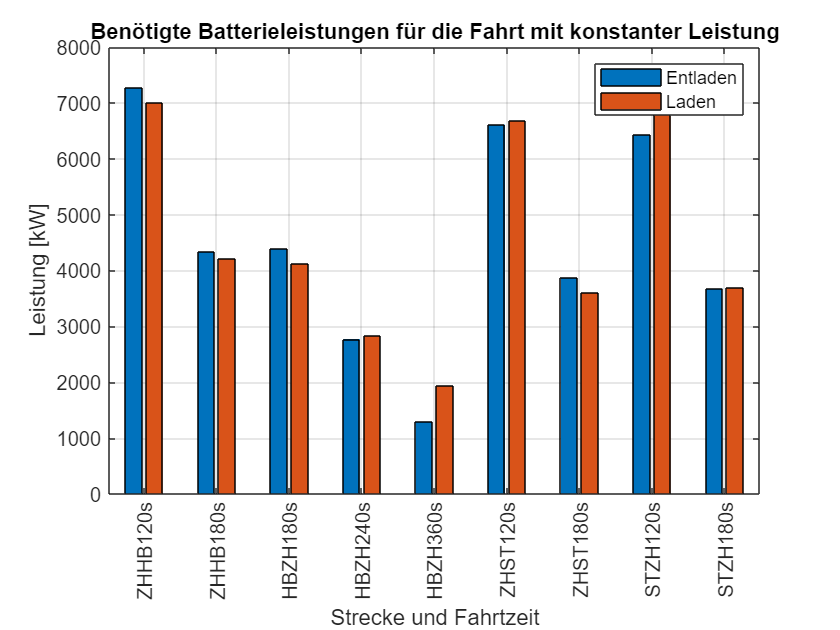


% Wenn P_thresh im vorhinein für jede Fahrt gleich angesetzt wird, so
% ergibt sich immer eine unterschiedliche Leistung für das Laden und Entladen
% Dies wird in den nachfolgenden Darstellungen verdeutlicht:

fnEntladen = fieldnames(PBatMaxEntladen);
fnLaden = fieldnames(PBatMaxLaden);
cla reset
for n = 1:length(fnEntladen)
    PBatMax(n,1) = abs(PBatMaxEntladen.(fnEntladen{n})); 
    PBatMax(n,2) = PBatMaxLaden.(fnLaden{n});
    label(n) = {string(fnEntladen{n}(1:2)) + string(fnEntladen{n}(4:5)) +  string(fnEntladen{n}(15:17)) + 's'};
end
 
bar(PBatMax)
set(gca, 'xtick', 1:numel(fnEntladen), 'xticklabel', label)
xtickangle(90)
ylabel('Leistung [kW]')
xlabel('Strecke und Fahrtzeit')
legend('Entladen', 'Laden')
title('Benötigte Batterieleistungen für die Fahrt mit konstanter Leistung')
grid()

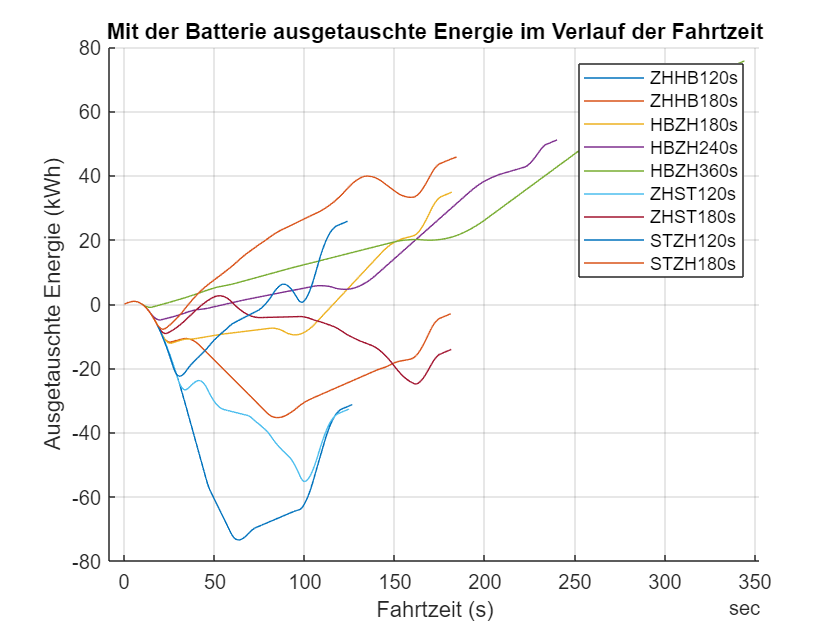


% Die nächsten Darstellungen zeigen den Verlauf der mit der Batterie
% ausgetauschen Energie (kumuliert) über die verschiedenen Fahrten.
% Dabei entspricht die positive Richtung einem Laden und negativ einem Entladen.
% aus dieser kumulierten Energie lässt sich auch die benötigte
% Batteriekapazität berechnen.
cla reset
BatDataNames = fieldnames(BatData);
hold on
for n = 1:length(BatDataNames)
    plot(BatData.(BatDataNames{n}).time, BatData.(BatDataNames{n}).EBatCUM/3600)
end
legend(label)
xlabel('Fahrtzeit (s)')
ylabel('Ausgetauschte Energie (kWh)')
title('Mit der Batterie ausgetauschte Energie im Verlauf der Fahrtzeit')
grid()

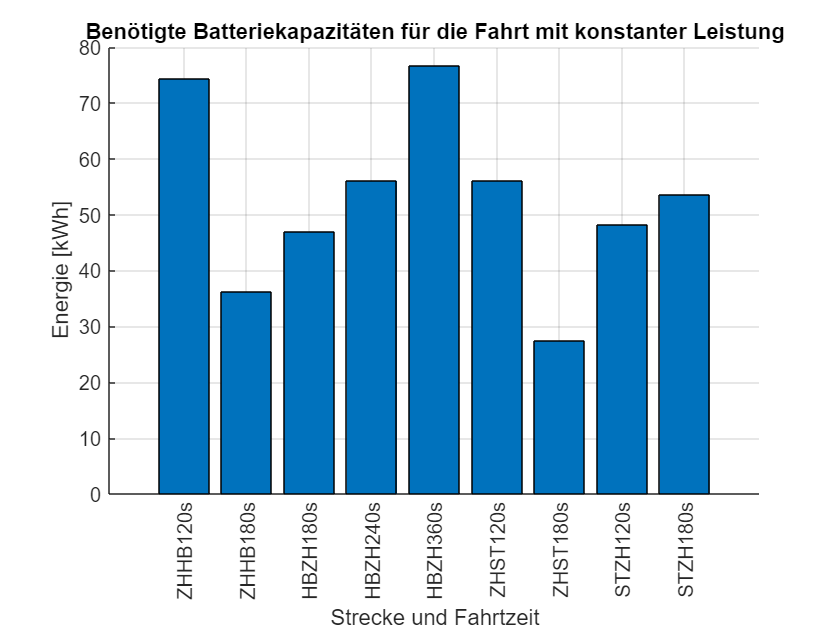


% Darstellung der benötigten Batteriekapazitäten für die einzelnen Fahrten:
fnEBatMax = fieldnames(EBatMax);
cla reset
hold on
for n = 1:length(fnEBatMax)
    EBat(n,1) = EBatMax.(fnEBatMax{n})/3600;
end
bar(EBat)
set(gca, 'xtick', 1:numel(fnEBatMax), 'xticklabel', label)
xtickangle(90)
ylabel('Energie [kWh]')
xlabel('Strecke und Fahrtzeit')
title('Benötigte Batteriekapazitäten für die Fahrt mit konstanter Leistung')
grid()

% Auswirkung der Batterie für den konstanten Leistungsbezug auf den
% gesamten Leistungsverlauf:

% load("BatterieSimulationenDoppeltRecharging.mat");
time = seconds(0:0.1:86399.9)';
time.Format = 'hh:mm:ss.S';
P_totConst = array2table(time);
P_totConst.P_Const = zeros(864000,1);

fn = fieldnames(CompleteData);

% Die vorher festgelegte Schwellwertleistung muss jetz zu den richtigen Zeitpunkten in
% die Tabelle geschrieben werden. Wenn mehrere Züge gleichzeitig auf der
% Strecke verkehren, so addiert sich deren bezogene Leistung.

for k = 1:numel(fn)
    index = find(P_totConst{:,1} == CompleteData.(fn{k}).time(1));
    if (isempty(index))
        index = find(string(P_totConst{:,1}) == CompleteData.(fn{k}).time(1));
    end
    P_totConst.P_Const(index:index + height(CompleteData.(fn{k}))) = P_totConst.P_Const(index:index + height(CompleteData.(fn{k}))) + P_thresh;
end

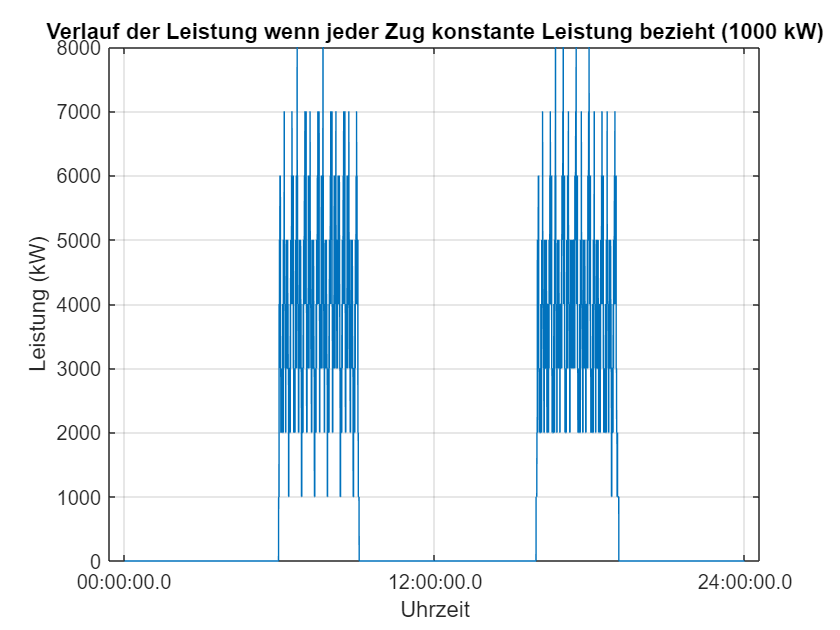

% neue Leistung über den simulierten Tag und Vergleich mit der simulierten
% Leistung:

% Neue Leistung wenn jedes Fahrzeug zu jedem Zeitpunkt eine gewisse
% Leistung vom Netz bezieht. Den ausgleich für die simulierte Leistung
% kommt jeweils von der Batterie, welche geladen und entladen wird.
cla reset
plot(time, P_totConst.P_Const)
xlabel('Uhrzeit')
ylabel('Leistung (kW)')
title('Verlauf der Leistung wenn jeder Zug konstante Leistung bezieht (' + string(P_thresh) + ' kW)')
grid()

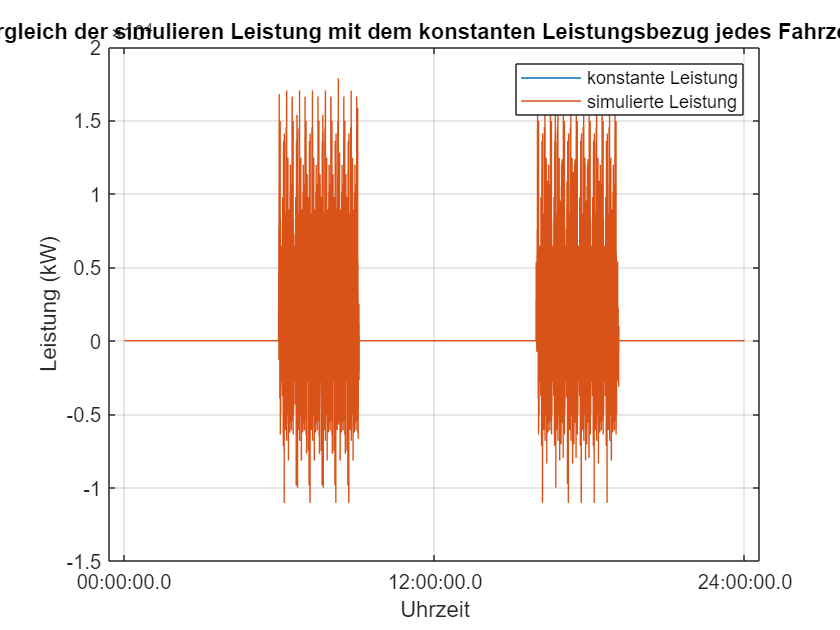


% Vergleich der neu berechneten Leistung mit der bisher simulierten
% Leistung:

plot(time, P_totConst.P_Const)
hold on
plot(time, P_tot)
hold off
xlabel('Uhrzeit')
ylabel('Leistung (kW)')
title('Vergleich der simulieren Leistung mit dem konstanten Leistungsbezug jedes Fahrzeuges')
legend('konstante Leistung', 'simulierte Leistung')
grid()

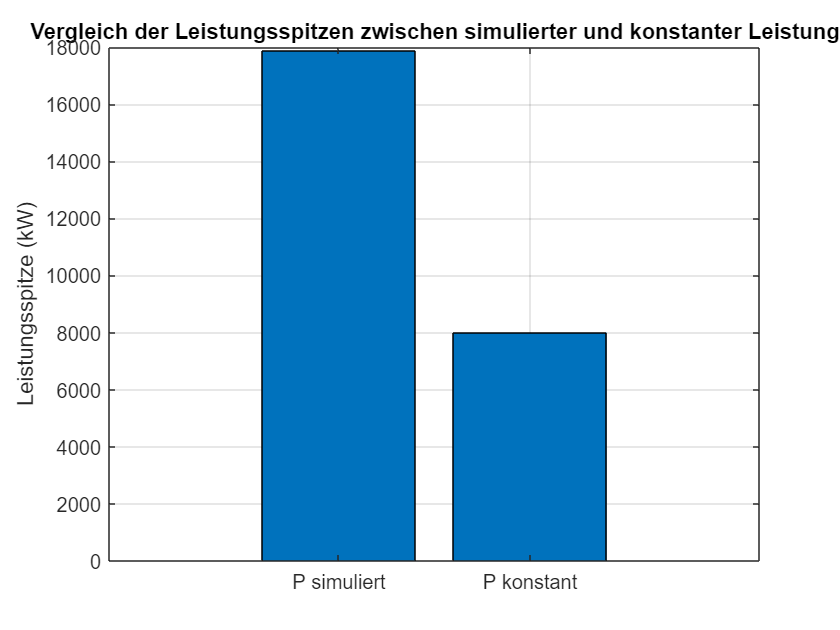


% Vergleich der höchsten Spitzen
MaxPSim = max(P_tot);
MaxPConst = max(P_totConst.P_Const);
bar([MaxPSim MaxPConst])
grid()
ylabel('Leistungsspitze (kW)')
title('Vergleich der Leistungsspitzen zwischen simulierter und konstanter Leistung')
xticklabels({'P simuliert'; 'P konstant'})

## Vergleich der neuen 8-min Mittelwerte

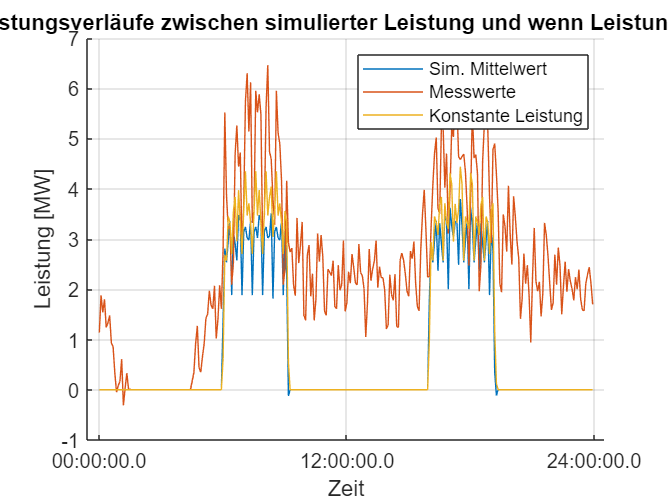

Import_measurements2; % Laden der Messungen von SBB

% Berechnung der 8Min Mittelwerte für die normale simulierte Leistung:
n = 1;
for i = 1:3000:864000
    if (i < 4800)
        P_totMean(n) = mean(P_tot(1:i));        
    else
        P_totMean(n) = mean(P_tot(i-4800:i));        
    end
    n = 1+n;
end

% Berechnung der 8Min Mittelwerte für die neue Leistung mit Batterie für konstante Leistung:
n = 1;
for i = 1:3000:864000
    if (i < 4800)
        P_totConstMean(n) = mean(P_totConst.P_Const(1:i));
    else
        P_totConstMean(n) = mean(P_totConst.P_Const(i-4800:i));
    end
    n = 1+n;
end


% Erstellung eines Zeitarrays für die 5 min. Mittelwerte (alle 5 Min.)
time2 = seconds(0:300:86400-300);
time2.Format = 'hh:mm:ss.S';
cla reset

% Darstellung und Vergleich der neuen Mittelwerte
hold on
plot(time2, P_totMean/1000)
plot(time2, Meas.P8minMittelMW(1:length(time2))) % Plotten der Messwerte der SBB
plot(time2, P_totConstMean/1000)
title('Vergleich der 8min Leistungsverläufe zwischen simulierter Leistung und wenn Leistung konstant gehalten wird')
xlabel('Zeit')
ylabel('Leistung [MW]')
legend('Sim. Mittelwert', 'Messwerte', 'Konstante Leistung')
grid()
%plot(time2, P_totPeakMean)
hold off

## speichern der Variablen

%save("BatterieSimulationenKonstantesP", 'BatData', 'CompleteData', 'EBatMax', 'P_thresh', 'P_tot', 'P_totConst', 'P_totConstMean', 'PBatMaxEntladen', 'PBatMaxLaden')
load("BatterieSimulationenKonstantesP.mat");